# **MEC3079S: Control Systems**

# Chapter 12 — Frequency domain design

## 12.1 Introduction

In **Chapter 10**, we develop a mathematical and visual framework in order to assess and design for intended steady-state error behaviour for a range of expected reference signals. We then considered transient closed-loop design specifications on the complementary sensitivity function magnitude in **Chapter 11**, and were able to repose these specifications in the log-polar plane, where assessment of $L(s)$ indicates adherance to the prescribed specifications. However, we have not yet outlined a methodical design procedure in order to shape $L(s)$ such that it meets the generated frequency domain boundaries. We will now consider this crucial final step of the analysis and design process, starting from the simplest of feedback controllers, to more complex and involved controllers.

### 12.1.2 High-frequency controller gain

With reference to the figure below, the transfer behaviour from noise, $N(s)$, to the control action, $U(s)$, is a by

$\frac{U(s)}{N(s)}=\frac{-G(s)}{1+P(s)G(s)}$.

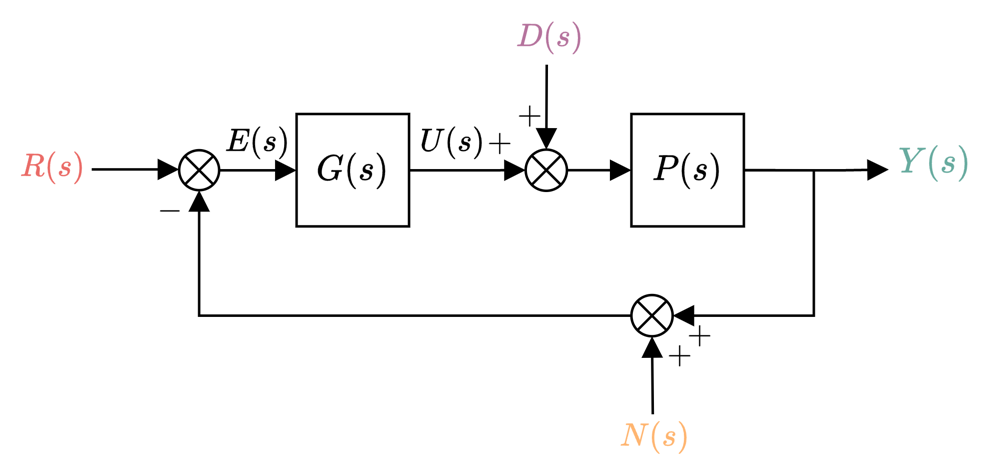

As previously discussed, we desire $L(s)$ to be strictly proper (have more poles than zeros), as this will reduce the effect of noise on the output signal at high frequencies, based on

$\frac{Y(s)}{N(s)}=\frac{-P(s)G(s)}{1+P(s)G(s)}$.

If $P(s)$ is additionally strictly proper, which is common in electromechanical systems, then at high-frequencies the transfer behaviour from $N(s)$ to $U(s)$ is

$\lim_{s\rightarrow \infty}\frac{U(s)}{N(s)}=\lim_{s\rightarrow \infty}\frac{-G(s)}{1+P(s)G(s)}=-G(\infty)$.

In other words, at high frequencies, the noise signal makes its way to the plant input based on the high-frequency gain of $G(s)$. Because we do not want high-frequency noise to act on our system, we therefore should design $G(\infty)$ to be as small as possible. As we will show later, we can even design $G(s)$ such that $G(\infty)=0$, but this will be discussed later in the Chapter.

## 12.2 Proportional controller design

### 12.2.1 Definition

As previously introduced, the **proportional (P)** controller is defined by

$G(s)=K$,

where $K$ is a real number, which we will assume is always positive. The name stems from the fact that the control action, $u(t)$, is directly proportional to the tracking error, $e(t)=r(t)-y(t)$, namely

$u(t)=Ke(t)=K\left[r(t)-y(t)\right]$.

The proportional controller is the simplest of control schemes, as we only need to change a single parameter, which has constant gain and phase across all frequencies. Considering the block diagram below, the loop transfer function for a unity feedback system is given by $L(s)=G(s)P(s)$, with a corresponding frequency response of $L(j\omega)=G(j\omega)P(j\omega)$.

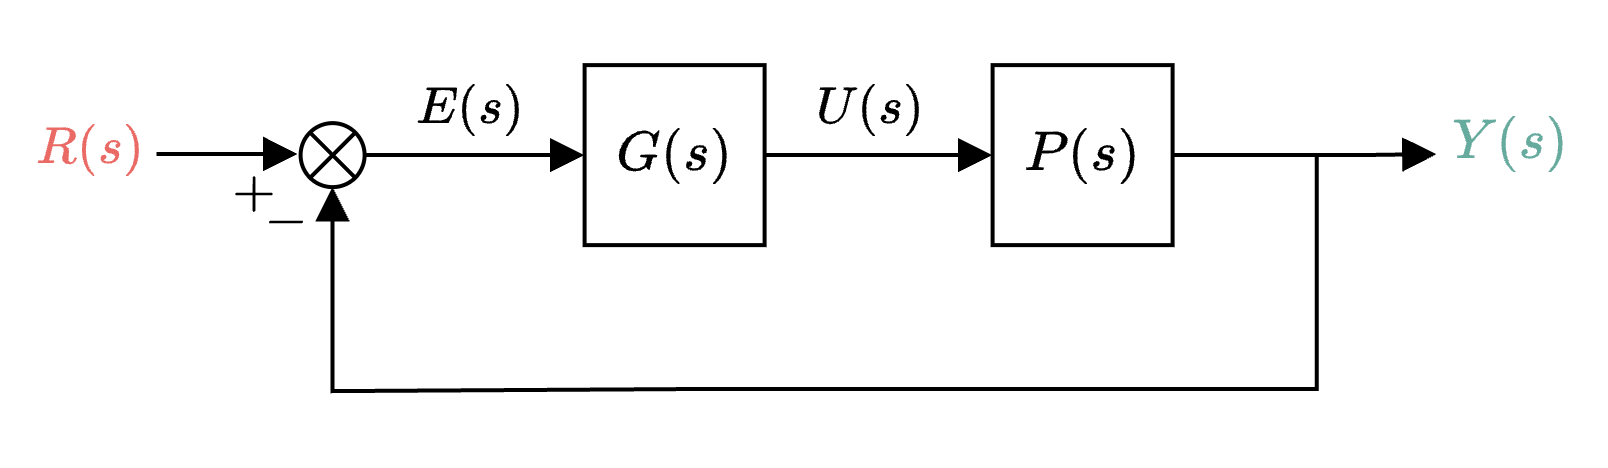

If we now substitute $G(s)=K$, then our loop transfer function becomes

$L(s)=KP(s)$, 

with the corresponding block diagram as shown below.

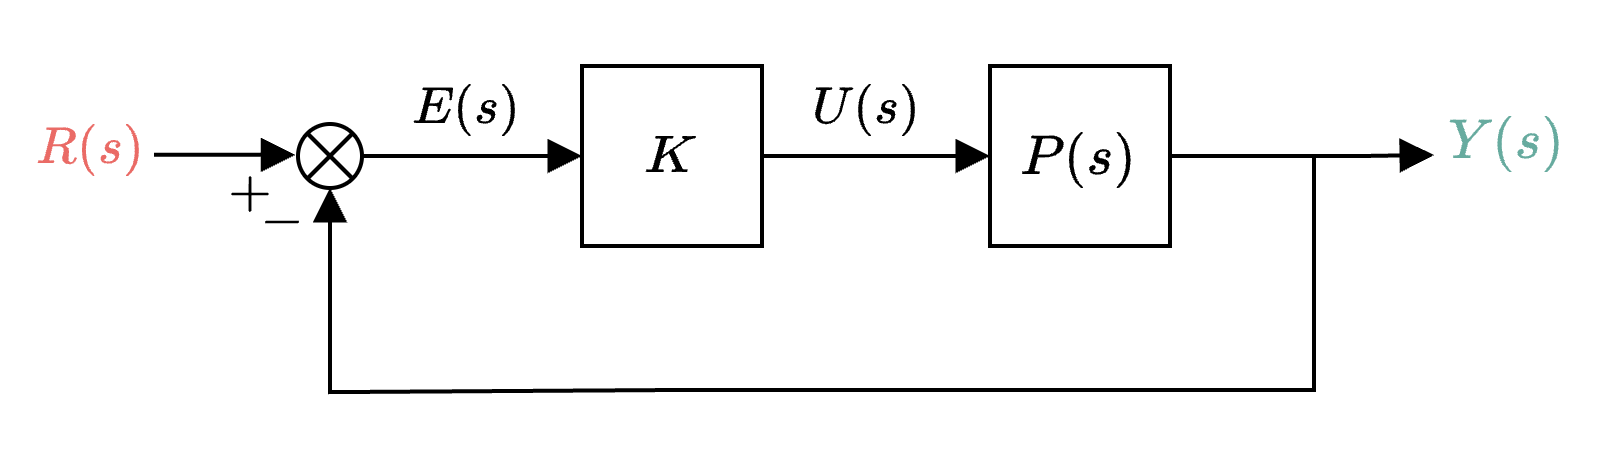

### 12.2.2 Frequency response

The frequency response of $G(s)$ is given by

$G(j\omega)=K$, 

which implies that the magnitude response (in dB) and phase response (in degrees) is

$20\log_{10}|G(j\omega)|=20\log_{10}|K|$,

and

$\angle\{ G(j\omega)\}\frac{180}{\pi}=\angle\{ K\}\frac{180}{\pi} = 0^\circ$,

respectively. The magnitude response (in decibels) and phase response (in degrees) of $L(s)=G(s)P(s)=KP(s)$ is determined as

$|L(j\omega)|_{dB}=20\log_{10}\{\left|KP(j\omega)\right|\}=20\log_{10}\left|K\right|+20\log_{10}\left|P(j\omega)\right|$,

and

$\angle L(j\omega)=\angle\{KP(j\omega)\}=\angle\{K\}+\angle\{P(j\omega)\}= \angle\{P(j\omega)\}$,

respectively. In other words, the phase response of $L(j\omega)$ is unaltered by $G(s)=K$, whereas the logarithmic magnitude response will be shifted up or down, depending on whether $K$ is greater than or less than $1$.

The code below generates the log-polar plots of $P(s)=\frac{1}{s(1+s/5)}$ and $L(s)=KP(s)=\frac{K}{s(1+s/5)}$.

clear 
s = tf('s');

P = 1/s/(1+s/5);

K = 3;
L = K*P;

figure, hold on
nichols(P)
nichols(L)
legend('$P(j\omega)$','$L(j\omega)$','interpreter','latex','Location','southeast')

We observe that for $K>1$, the $L(j\omega)$ locus is shifted up, relative to the $P(j\omega)$ locus, whereas for $K<1$, the $L(j\omega)$ locus is shifted down.

### 12.2.3 Designing for margins of stability

Recall that when using a log-polar plot, the gain margin corresponds with the amount of gain required to raise the curve such that it passes through the critical point, which occurs at the phase crossover frequency $\omega_{pc}$. The phase margin (in degrees) corresponds to the amount of phase required to shift the curve leftwards such that it passes through the critical point, which occurs at the gain crossover frequency $\omega_{gc}}$. This is illustrated below.

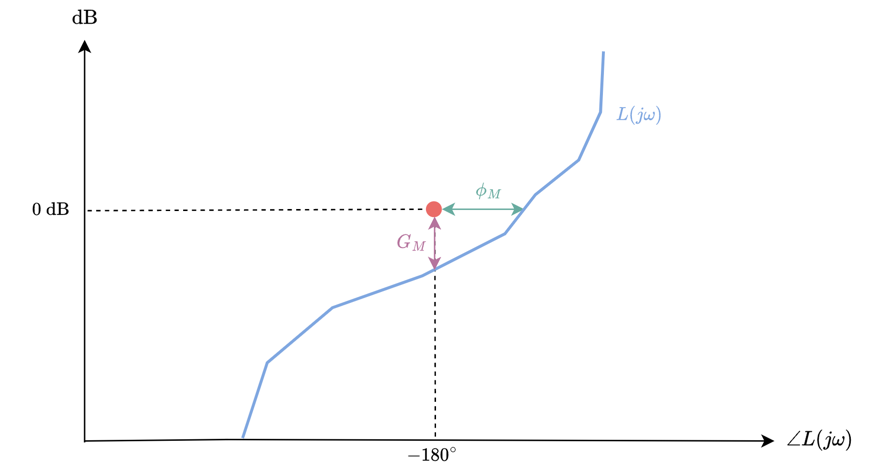

If the *desired* gain and phase margins are marked on the log-polar plot, then we can adjust $K$ to *attempt* to meet the required margins of stability. Based on the limitations of $G(s)=K$, we can only shift the $L(j\omega)$ locus up and down, but depending on the structure of $P(s)$ it may be possible to adjust the gain of $L(j\omega)$ via $K$ in order to adhere to the gain and phase margins.

#### Example

*Using a log-polar plot, design a proportional feedback controller that provides a phase margin of *$\phi_M\geq 45^\circ$, and gain margin of $G_M>6$ dB, for the open-loop plant $P(s)=\frac{10}{s(1+s/2)(1+s/5)}$.

We begin by marking our log-polar plot for the gain and phase margin requirements. For the phase margin, we need to have a phase angle greater than $-135^\circ$ at the gain crossover frequency, so we make a mark at the coordinate $(-135^\circ,0)$, with the requirement that $L(j\omega)$ passes to the *right* of this mark. For the gain margin, we need to be at least $6$ dB below the critical point when at the phase crossover frequency, so we make a mark at the coordinate $(-180^\circ,-6)$, with the requirement that the $L(j\omega)$ locus passes *below* this mark.

The code below generates the log-polar plot of $L(s)=KP(s)$, and also includes the markers for the gain and phase margins.

clear 
s = tf('s');

P = 10/s/(1+s/5)/(1+s/5);

K = 0.01;
L = K*P;

figure, hold on
nichols(L)
plot(-135,0,'r>',MarkerFaceColor='red') %phase margin marker
plot(-180,-6,'rv',MarkerFaceColor='red') %gain margin marker
legend('$L(j\omega)$','interpreter','latex','Location','southeast')

Using the code above, when $K=1$, we are not meeting the gain and phase margins. In fact, our closed-loop system will be unstable for $K=1$, as $L(j\omega)$ is intercepting the critical point. We therefore need to reduce the gain of $L(j\omega)$ by using $K<1$. After some experimenting, we can show that for $K\leq 0.24$ we can meet both the gain and phase margin requirements. Note that we have ended up with a gain margin greater than our specification, as a result of only have a single degree of freedom in our feedback controller (only a single parameter can be varied). We could increase the order of $G(s)$ to reduce the overdesign, but this will be covered later in the Chapter.

Note that there does not necessarily exist a $G(s)=K$ value that simultaneously satisfies both the gain and phase margin requirements. If this is the case, then we should consider using a higher order controller, such as a lead controller (see **Section 12.4**).

### 12.2.4 Designing for steady-state error

As shown in **Chapter 10**, we can use frequency response visualisations in order to infer expected steady-state error performance. Recall that the position error constant is given by

$K_p=\lim_{s\rightarrow 0}L(s)$,

and the associated steady-state error for unit step inputs is given by

$e(\infty)=\frac{1}{1+K_p}$.

Given that $G(s)=K$, and by extension, $L(s)=KP(s)$, this means that 

$K_p=K\lim_{s\rightarrow 0}P(s)$.

For Type-0 $P(s)$, $K_p$ will be finite ($K_p<\infty$), which we can read off from the log-polar plot of $L(j\omega)$ by measuring the gain when $\omega=0$. Based on this, if we are given a finite steady-state error specification for a step input, then we can determine $K_p$ using

$K_p=\frac{1}{e(\infty)}-1$.

With the desired $K_p$ determined, we can then mark of $|K_p|_{dB}$ on our log-polar plot, and then ensure that $L(j0)$ lies above the desired $|K_p|_{dB}$ line.

#### Example

*Using a log-polar plot, design a proportional controller that results in a steady-state error *$e(\infty)\leq 0.1$ for $P(s)=\frac{5}{1+s/12}e^{-0.01s}$.

Using our formula for desired position error constant, we get

$K_p=\frac{1}{e(\infty)}-1=\frac{1}{0.1}-1=9$.

The code below generates the log-polar plot of $L(j\omega)=KP(j\omega)$, and also indicates the $|K_p|_{dB}=20\log_{10}|K_p|$ line, which we need to stay above.

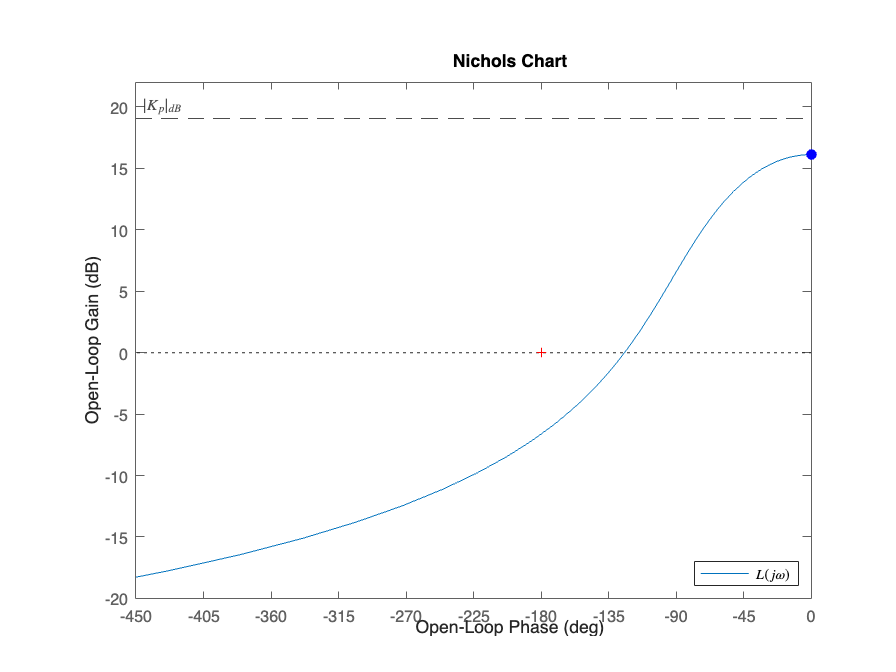

clear 
s = tf('s');

P = 5/(1+s/12)*exp(-0.01*s);

K = 1.28;
L = K*P;

Kp = 9;

figure, hold on
nichols(L)

plot(0,20*log10(K*dcgain(P)),'ob',MarkerFaceColor='b')
yline( 20*log10(Kp),'--k','$|K_p|_{dB}$','Interpreter','latex','LabelHorizontalAlignment','left')
ylim([-20,22])
legend('$L(j\omega)$','','','interpreter','latex','Location','southeast')

For $K=1$, $L(j0)$, highlighted with the blue marker, is below the desired $|K_p|_{dB}$ line. We therefore need to increase $K$ in order to place $L(j0)$ on or above the desired $|K_p|_{dB}$ line. With a gain of $K=1.8$, we can meet the steady-state error requirement. Note that we could have also determined $K$ algebraically using 


$$K=\frac{K_p}{\lim_{s\rightarrow 0}P(s)}=1.8.$$


It is often useful to represent the static error constant requirement in a log-polar plot, as the particular system may also have margins of stability or transient design specifications to consider. For example, if the closed-loop system also has a phase margin requirement of $\phi_M\geq 40$, then the current design would violate this, as shown using the code below, which would necessitate a higher-order feedback controller. 

clear 
s = tf('s');

P = 5/(1+s/12)*exp(-0.01*s);

K = 1.8;
L = K*P;

Kp = 9;

figure, hold on
nichols(L)

plot(-135,0,'r>',MarkerFaceColor='red') %phase margin marker
plot(0,20*log10(K*dcgain(P)),'ob',MarkerFaceColor='b')
yline( 20*log10(Kp),'--k','$|K_p|_{dB}$','Interpreter','latex','LabelHorizontalAlignment','left')
ylim([-20,22])

legend('$L(j\omega)$','','','interpreter','latex','Location','southeast')

In this scenario, and assuming we choose to stay with a P controller of $G(s)=K$, we would then have to choose between meeting the steady-state error specification, or phase margin specification. Alternatively, we could use a higher-order controller, as shown in the subsequent sections.

### 12.2.5 Designing for transient design specifications

**Chapter 11** introduced a methodology for representing design requirements on $L(j\omega)$, which can be visualised in a log-polar plot. We can now use our understanding of shifting the $L(j\omega)$ up/down using $K$ in order to *try* satisfy the prescribed design specifications for a particular plant. However, before commencing with the design of $G(s)=K$, we should be wary of the limitations of using a proportional controller:

- **Zero steady-state error** — because $G(s)=K$ is Type-0, $P(s)$, which we have no control over, would have to be the correct type number in order to ensure the required reference to output tracking. Additionally, Type-0 $G(s)=K$ means that plant input disturbances will never be rejected completely at steady-state. So if zero steady-state error to step-like disturbances is a system requirement, then a proportional controller is not a viable solution.

- **Transient design specifications **— depending on the structure of $P(s)$, a proportional controller will not necessarily be able to meet the prescribed transient design specifications. In other words, shifting the $L(j\omega)$ up/down in a log-polar plot may not provide the sufficient design degrees of freedom to meet the *stay-out *constraints on the loop transfer function. This would be another example where $G(s)=K$ is not a viable control solution. Notably, we often will not know whether $G(s)=K$ will be a viable solution for the prescribed transient design specifications until we try!

Assuming the aforementioned issues are not present, we can proceed with the proportional control design. 

#### Example

*Using a log-polar plot, design a proportional controller for the system, *$P(s)=\frac{10}{s(s+2)$*, which will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, and percentage overshoot of *$25$*%.*

Recall that $M_A$, representing the *stay-below *boundary when plotted against a Bode magnitude response, is determined using

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.35$.

For the *stay-above *boundary, we determine the desired bandwidth frequency using 

$\zeta=0.71$,

$\omega_n=\frac{4}{\zeta T_s}$, 

$\omega_0=\omega_n\sqrt{ (1-2\zeta^2)+\sqrt{4\zeta^4-4\zeta^2+2}}\approx \omega_n=1.12$ rad/s.

The *stay-above *magnitude bound is then chosen as $M_B=\frac{1}{\sqrt{2}}$, for frequencies $\omega\leq \omega_0$.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)=KP(j\omega)$. Frequency point $\omega=\omega_0$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_0$ to be outside (effectively above) the enclosed green region.

clear
s = tf('s');

P = 10/s/(s+2);
K = 0.17;
L = K*P;%specifications
OS = 25;
Ts = 5;

%stay-below bound
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 )

zeta = 0.4037

Ma = 1/( 2*zeta*sqrt(1-zeta^2) )

Ma = 1.3537

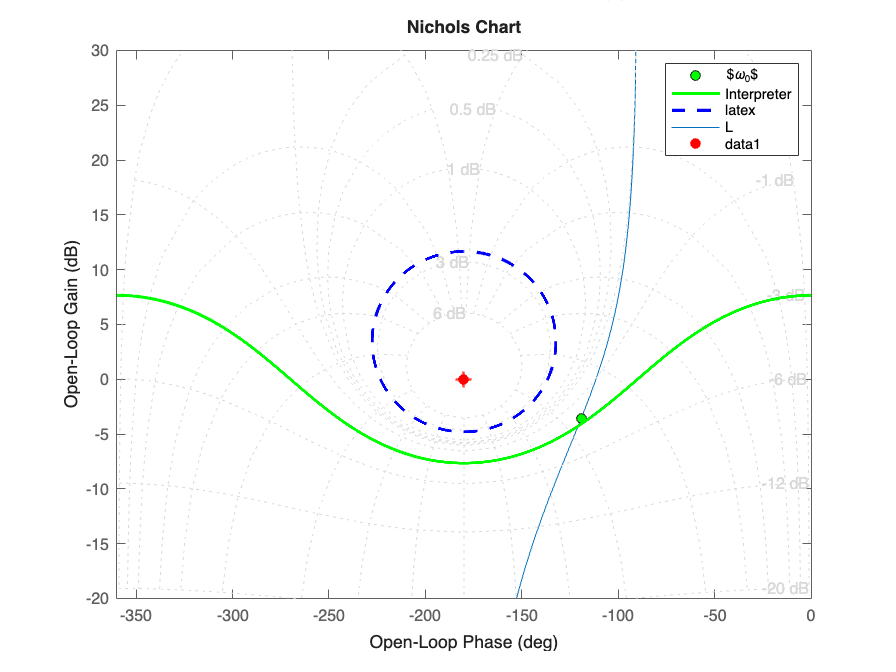


%stay-above bound
zeta = 0.71;
wn = 4/(zeta*Ts);
w0 = wn*sqrt( (1-2*zeta^2)+sqrt( 4*zeta^4-4*zeta^2+2 ) );
Mb = 1/sqrt(2);

figure, hold on
M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,w0) );

        plot(angle(Lw)*180/pi,20*log10(abs(Lw)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
nichols(L)
ngrid
ylim([-20 30])
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$\omega_0$','Interpreter','latex')

%legend("Position", [0.17488,0.1296,0.21607,0.086905])


For $K=1$, we see that although the design bound resulting from the bandwidth requirement ($|T(j\omega)|\geq M_B$) is met, the overshoot requirement ($|T(j\omega)|\leq M_A$) is not currently satfisfied. The only way for $L(j\omega)$ to exit the *stay-out* region (indicated with blue dotted lines) is to reduce the gain of $L(j\omega)$ sufficiently using $K<1$. For $K\approx 0.6$, both tracking constraints can be adhered to. 

At this point we could stop, but what we should also notice is that we can reduce the gain of $K$ further whilst still meeting both tracking requirements. As discussed earlier in the Chapter, we want to minimise the high-frequency gain of $G(s)$, which for the proportional controller is given by $K$. This is also beneficial, as reduced gain in the feedback controller results in a smaller control action, based on $u(t)=Ke(t)$, which means that our closed-loop system will be "cheaper" in terms of energy consumption and component wear. 

For a gain of $K\approx 0.17$ we can just meet the bandwidth requirement, whilst simultaneously easily meeting the overshoot constraint. We should therefore expect to closely adhere to the settling time requirement (as $L(j\omega_0)$ is now sitting right on the boundary condition for the bandwidth specification) whilst having overshoot substantially less than the worst-case allowance (as $L(j\omega)$ is now relatively far from the *stay-out *region originating from the overshoot specification). The corresponding closed-loop step response is generated from the code below, which matches our expectations.

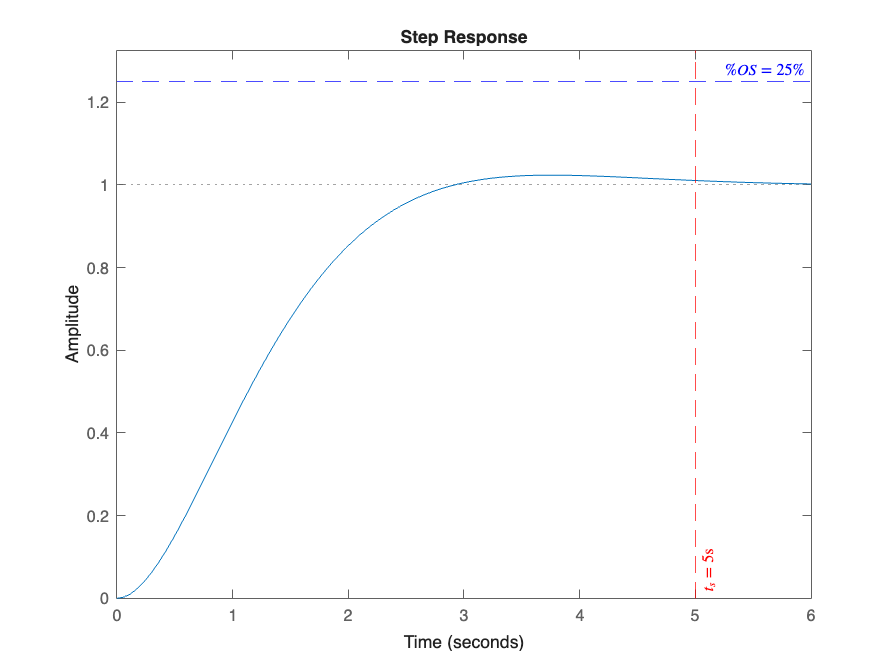

T = feedback(L,1);
figure, hold on
step(T,Ts+1)
yline(1.25,'--b','$\% OS=25\%$','Interpreter','latex')
xline(5,'--r','$t_s=5$s','Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1+1.3*OS/100])

## 12.3 Proportional-plus-integral controller design

A **proportional-plus-integral (PI)** controller is required in the following cases:

- The type number of $L(s)$ needs be increased by one to meet steady-state requirements with respect to reference signals. For example, if $P(s)$ is Type-0 and we require zero-error step reference tracking at steady-state, then $G(s)$ needs to be Type-1 to make $L(s)$ Type-1.

- $G(s)$ needs to be Type-1 to meet steady-state requirements with respect to plant input disturbances. Aside from the case above, this is required when there are plant input disturbances acting on the system and the user specifications requires that the disturbances be completely rejected at steady-state.

If neither of the above conditions apply, then we need not design an integral controller.

### 12.3.1 Definition

The PI controller is given by

$G(s)=K\frac{1+sT_i}{sT_i}$,

where $K$and $T_i$ are real-valued parameters that we seek to design. The name stems from the fact that a PI controller is made up by summing a proportional and integral controller, namely

$G(s)=K\frac{1+sT_i}{sT_i}=K+\frac{K}{T_is}$.

The PI controller contains a single pole, located at $p=0$ (at the origin in the $s$-plane), and a single zero, located at $z=\frac{-1}{T_i}$.

Using the two-term representation above, and noting that the control action is given by $U(s)=G(s)E(s)$, the relationship between tracking error and control action in the time-domain is obtained as

$u(t)=Ke(t)+\frac{K}{T_i}\int_{0}^te(t)\delta t$.

The PI controller therefore makes use of an integrator, which continually increases control action $u(t)$, via the term $K\int_{0}^te(t)$, until such time that $e(t)=0$. The term $T_i$ is known as the integral time constant, as decreasing $T_i$ increases the gain of the integrator term, $\frac{K}{T_i}\int_{0}^te(t)\delta t$.

### 12.3.2 Frequency response

The frequency response of our PI controller is given by

$G(j\omega)=K\frac{1+j\omega T_i}{j\omega T_i}$.

The (arithmetic) magnitude response of $G(j\omega)$ can be determined as

$|G(j\omega)|=\left|K\frac{1+j\omega T_i}{j\omega T_i}\right|=\frac{\left|K\right|\sqrt{1+\omega^2T_i^2}}{\omega T_i}$,

with the corresponding logarithmic magnitude response given by

$20\log_{10}|G(j\omega)|=20\log_{10}\{\frac{\left|K\right|\sqrt{1+\omega^2T_i^2}}{\omega T_i}\}$.

The phase response (in degrees) of our PI controller is calculated using

$\angle\{ G(j\omega)\}\frac{180}{\pi}=\angle\{ K\frac{1+j\omega T_i}{j\omega T_i}\}\frac{180}{\pi} = \tan^{-1}(\omega T_i)\frac{180}{\pi}-90^\circ$.

Using our derivation above for magnitude response, or using our formula for high-frequency gain, it can easily be shown that the high-frequency gain of our PI controller is

$G_{hf}=\lim_{s\rightarrow\infty}G(s)=\lim_{\omega\rightarrow\infty}G(j\omega)=K$.

Similarly, at high frequencies ($\omega\rightarrow \infty$) the phase behaviour of a PI controller tends to zero, based on

$\phi_{hf}=\lim_{\omega\rightarrow \infty}\angle\{ G(j\omega)\}\frac{180}{\pi}= \lim_{\omega\rightarrow \infty}\tan^{-1}(\omega T_i)\frac{180}{\pi}-90^\circ=0$.

This suggests that at high frequencies a PI controller behaves like a proportional controller of the form $G(s)=K$. Based on the equations above, we can also easily show that at low frequencies $\omega\rightarrow 0$, the gain becomes infinitely large, whereas the phase response tends to $-90^\circ$. This duality of the PI controller, namely infinite gain at low frequencies and finite gain with zero phase lag at high frequencies, is very useful when a controller is required in order to increase the type number of $L(s)$ by one, such as when full disturbance rejection at steady-state is required. Lastly, it is useful to observe that at the zero frequency of $\omega=\frac{1}{T_i}$, the magnitude response and phase response is given by

$|G(j\frac{1}{T_i})|=\sqrt{2}\left|K\right|$,

and

$\angle\{ G(j\frac{1}{T_i})\}\frac{180}{\pi}=-45^\circ$,

respectively. As a rule of thumb, the PI controller will behave like a proportional controller for frequencies at least one decade *above* the zero frequency, namely, $\omega\geq \frac{10}{T_i}$, and will behave like a pure integrator for frequencies less than one decade *below* the zero frequency, namely $\omega\leq \frac{1}{10T_i}$.

We can visualise the frequency response behaviour of a PI controller using a Bode diagram, as generated using the code below. The zero frequency, $|z|=\frac{1}{T_i}$, is also plotted, along with frequencies one decade above and below $|z|$.

clear 
s = tf('s');

K = 1;
Ti = 1;
G = K*(1+s*Ti)/(s*Ti);

z = 1/Ti;

figure, hold on
bode(G)

ax=findobj(gcf,'type','axes');
phase_ax=ax(1);
mag_ax=ax(2);

axes(mag_ax)
xline(z,'--k');
xline(z/10,'--k');
xline(10*z,'--k');
axes(phase_ax)
xline(z,'--k','$\omega=\frac{1}{T_i}$ rad/s','labelOrientation','horizontal','labelVerticalAlignment','bottom','Interpreter','latex');
xline(z/10,'--k','$\omega=\frac{1}{10T_i}$ rad/s','labelOrientation','horizontal','labelVerticalAlignment','bottom','Interpreter','latex');
xline(10*z,'--k','$\omega=\frac{10}{T_i}$ rad/s','labelOrientation','horizontal','labelVerticalAlignment','bottom','Interpreter','latex');

The Bode plot shows that for $\omega\geq \frac{10}{T_i}$, $G(s)\approx K$, and for $\omega\leq \frac{1}{10T_i}$, $G(s)\approx \frac{K}{sT_i}$.

### 12.3.3 Design methodology

Owing to the fact that a PI controller resembles that of a P controller of the form $G(s)\approx K$ at sufficiently high frequencies ($\omega\geq \frac{10}{T_i}$), we can begin by designing our controller under the assumption that it is simply a proportional controller. One way of doing this is to initially set the integral time constant, $T_i$, to a sufficiently large number, thereby making the zero frequency, $|z|$, very low. We can then design $G(s)\approx K$ in the same manner as previously in order to meet the required stability and/or transient tracking requirements. Once we have met those requirements, we can then begin to decrease $T_i$. Importantly, we still need $T_i$ to be sufficiently large, otherwise the integral action will take a very long time to reduce the tracking error to zero. We therefore want a small enough $T_i$ value that also does not interfere with the tracking and stability design specifications.

In order to ensure that $\left|T(j\omega)\right|$ approaches unity, we shall adjust our *stay-above *bandwidth contraint from before such that the lower bound repesents $\left|T(j\omega)\right|\approx 1$ for the desired frequency bandwidth. In order to not be too overly constraining on the closed-loop gain, we use a lower bound magnitude of $M_B=0.98$ (or approximately $-0.18$ dB), for example, instead of $M_B=1$, with a frequency range of $\omega\leq \omega_p$, where $\omega_p$ is the peak frequency of a second-order system, which we previously defined as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}$.

The figure below shows the proposed boundaries for $\left|T(j\omega)\right|$

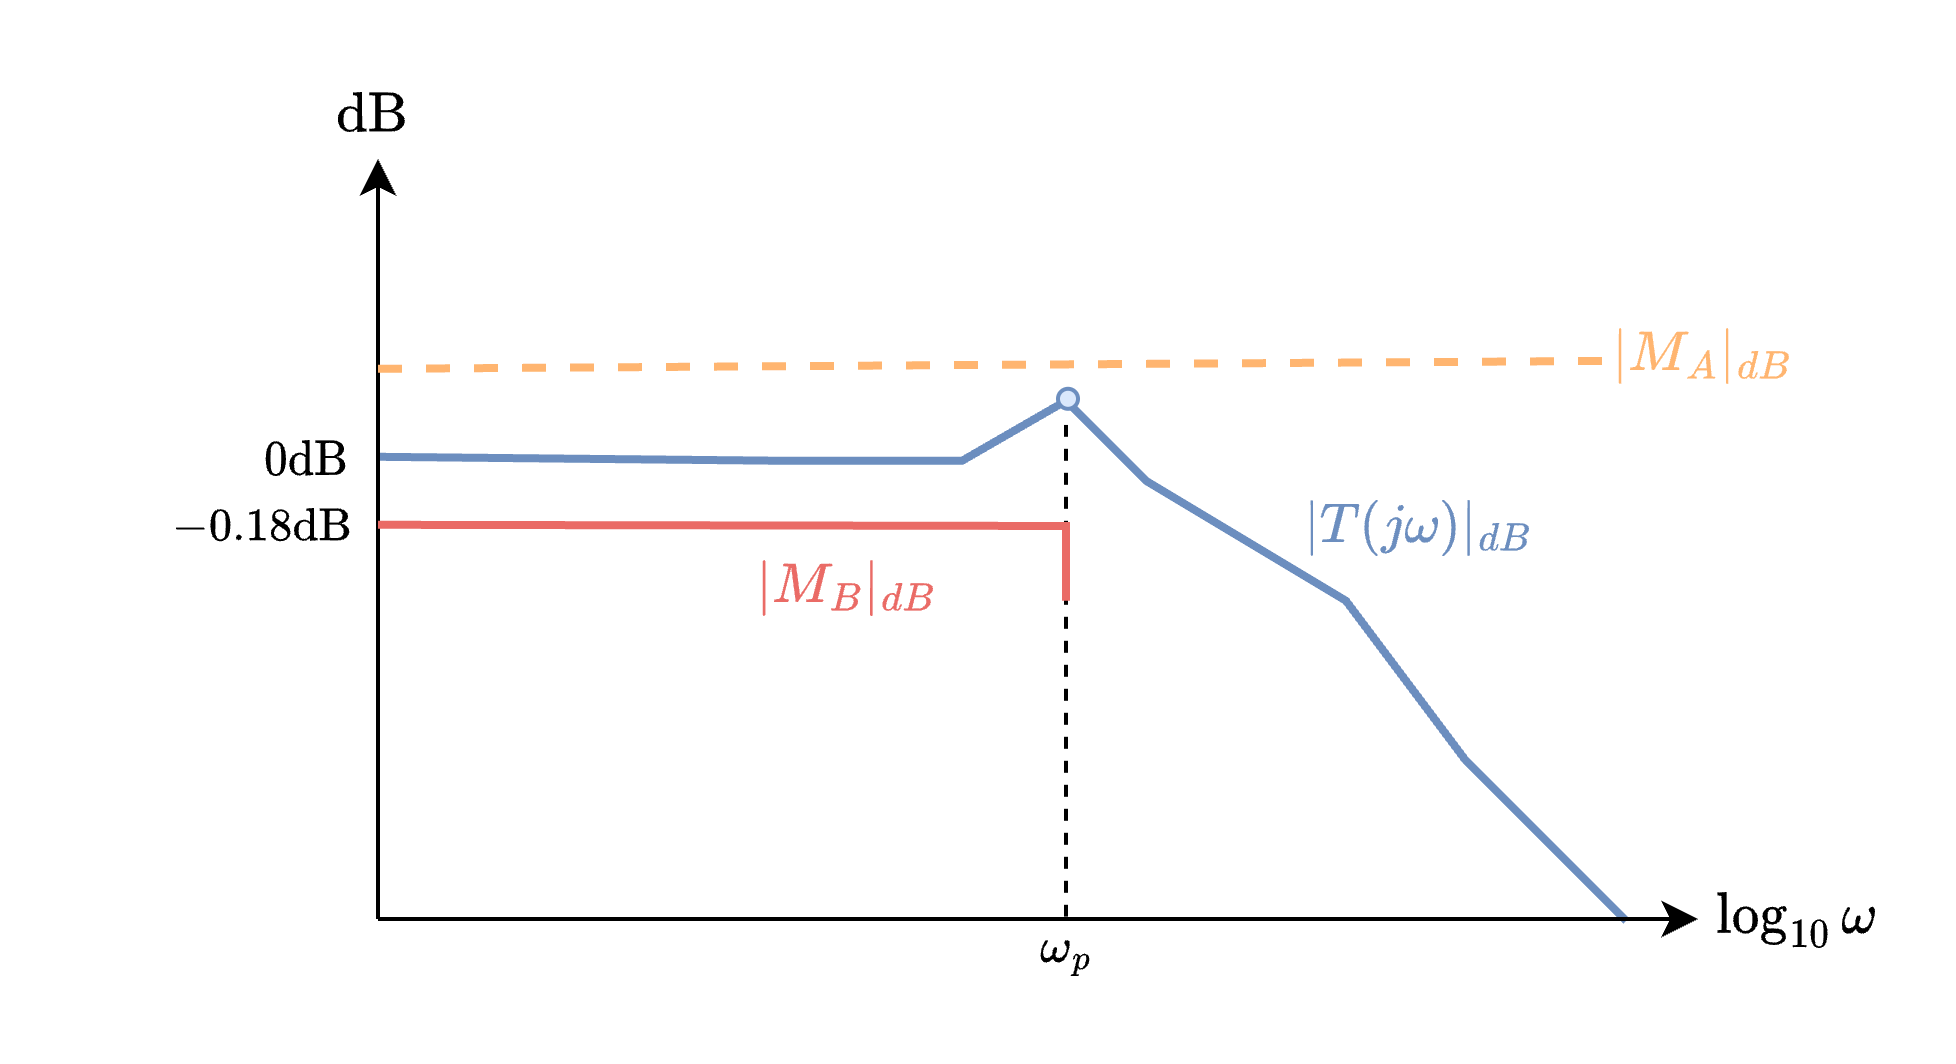

#### Example 1

*Using a log-polar plot, design a first-order controller for the system, *$P(s)=\frac{1}{s(s+2)}$*, which will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, and percentage overshoot of *$25$*%, and fully reject input disturbances at steady-state.*

In order to fully reject disturbances at steady-state, we required $G(s)$ to be at least Type-1, so we need to design a PI controller. We have already determined $M_A$ from the previous example with the same specifications as

$M_A=1.35$.

Using the outline PI controller design approach, we set $M_B=0.98$, and then determine the peak frequency based on the natural frequency and damping ratio of the *stay-above *bound, which gives

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=1.98\sqrt{1-2(0.4)^2}=1.63$.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)=P(j\omega)G(j\omega)$. Frequency point $\omega=\omega_p$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_p$ to be above green line, which corresponds with $|T(j\omega)|\geq M_B$.

clear
s = tf('s');

P = 0.2/s/(s+2.2)

P =
 
      0.2
  -----------
  s^2 + 2.2 s
 
Continuous-time transfer function.
Model Properties


K = 1

K = 1

Ti = 100;
G = K*(1+s*Ti)/(s*Ti);
% G = K/s;
L = P*G;

Ts = 5;
OS = 20;

%stay-below bound
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 )

zeta = 0.4559

Ma = 1/( 2*zeta*sqrt(1-zeta^2) );

%stay-above bound
wn = 4/(zeta*Ts);
w0 = wn*sqrt( (1-2*zeta^2)+sqrt( 4*zeta^4-4*zeta^2+2 ) );
Mb = 0.98;


wp = wn*sqrt(1-2*zeta^2)

wp = 1.3411

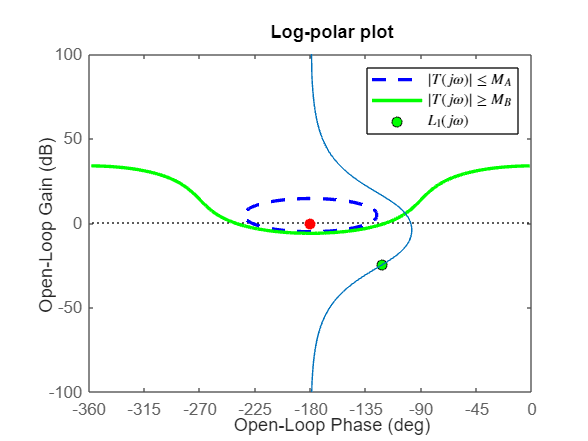


figure, hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
nichols(L)

plot(-180,0,'ro',MarkerFaceColor='r')

legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$', '$L_1(j\omega)$','Interpreter','latex')
title('Log-polar plot')
xlim([-360,0])
hold off

For $K=1$ and $T_i=100$, the overshoot requirement is met (staying outside the blue circle), but the bandwidth and low-frequency gain requirement (being above the green line) is not met. We therefore need to increase $K$. Setting $K=4$ is sufficient to meet both specifications. We can then begin to reduce the integral time constant. Because the zero frequency increases as $T_i$ is reduced, we end up with less phase lead at all frequencies, which also begins to make satisfying both boundaries a bit more challenging. With $K=4$ and $T_i=20$, we can closely meet both frequency-domain design constraints, but checking the time-domain step response below shows that our output response does not settle (stay within the $2\%$ band) as required by the settling time specification. We therefore need to make some minor adjustments to $K$ and $T_i$ in order to correct for this. Increasing the gain slightly to $K=5.5$ resolves the settling time issue whilst also (just) meeting the overshoot specification, as exhibited by the time-domain step response. 

L

L =
 
     20 s + 0.2
  -----------------
  100 s^3 + 220 s^2
 
Continuous-time transfer function.
Model Properties


T = feedback(L,1);
figure, hold on
step(T,Ts+10)
stepinfo(T)

ans = struct with fields:
         RiseTime: 18.3046
    TransientTime: 185.4989
     SettlingTime: 185.4989
      SettlingMin: 0.9014
      SettlingMax: 1.0763
        Overshoot: 7.6326
       Undershoot: 0
             Peak: 1.0763
         PeakTime: 55.4102


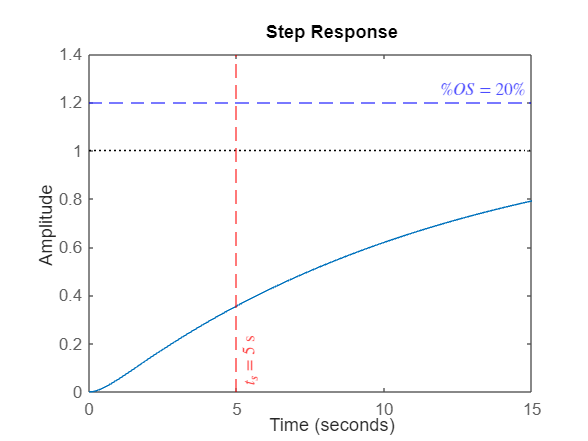

yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

Note that instead of increasing $K$, we could have also increased $T_i$, for example if we were not concerned with a larger integral time constant. This example also illustrates that our simplified frequency-domain *stay-above *and *stay-below* boundaries are only approximating the intended time-domain behaviour. So we must always check that the time-domain behaviour matches the original specifications, and make refinements to $G(s)$ if the user requirements are not met.

#### Example 2

*Design a feedback controller for the system, *$P(s)=\frac{5}{1+s}$*, that will result in zero-error step reference tracking at steady state, and also satisfy the closed-loop second-order specifications of a settling time of *$10$* seconds, and percentage overshoot of *$10$*%,.*

$P(s)$ is Type-0, so we need $G(s)$ to be at least Type-1 in order to achieve zero error tracking at steady-state for step reference signals. For the percentage overshoot and settling time specification, we can determine the corresponding $\zeta$ and $\omega_n$ values as

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.59$,

and

$\omega_n=\frac{4}{\zeta T_s}=0.68$,

respectively. Finally, the peak response of the *stay-below *bound is determined by

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.05$.

Using the outline PI controller design approach, we set $M_B=0.98$, and then determine the peak frequency based on the natural frequency and damping ratio of the *stay-above *bound, which gives

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=0.37$.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)=P(j\omega)G(j\omega)$. Frequency point $\omega=\omega_p$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_p$ to be outside (effectively above) the enclosed green region.

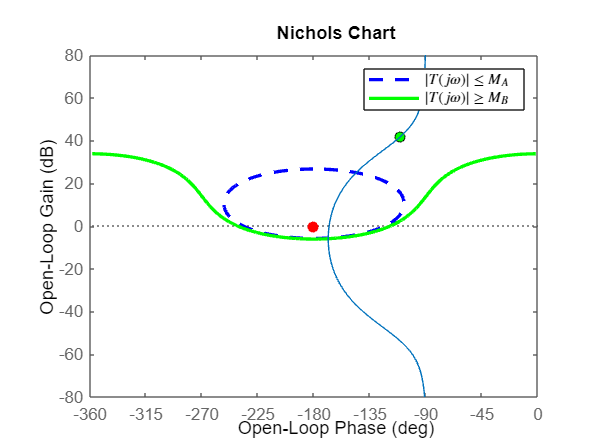

clear
s = tf('s');

P = 0.5/(1+s);
K = 1;
Ti = 0.01;
G = K*(1+s*Ti)/(s*Ti);
% G = K/s;
L = P*G;

Ts = 10;
OS = 10;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

figure, hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

nichols(L)
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
xlim([-360,0])

For $K=1$ and $T_i=1$, the overshoot requirement is met (staying outside the blue circle), but the bandwidth and low-frequency gain requirement is not met. We therefore need to increase $K$. Setting $K=5$ is sufficient to meet both specifications. We can then begin to reduce the integral time constant. With $K=5$ and $T_i=0.5$, we can meet both design constraints, but at this point we can also significantly reduce the high-frequency gain of $G(s)$ using $K$. With $K=1$ and $T_i=0.5$, the frequency domain bounds are met whilst also keeping $K$ small. Note that we could make $K$ even smaller if we make $T_i$ smaller and incur additional phase lag.

Checking the time-domain step response shows that we meet both user specifications.

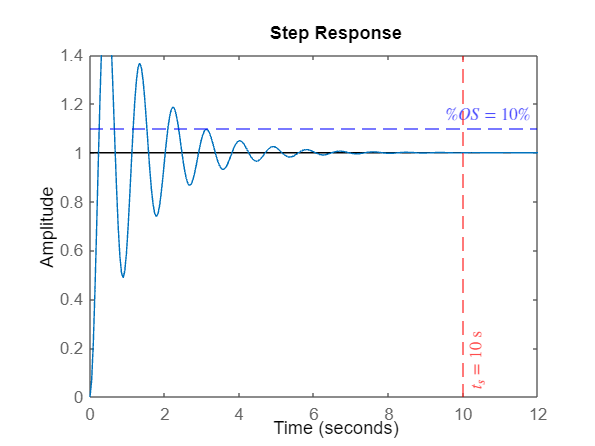

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

## 12.4 Proportional-plus-deriviative controlller design

A **proportional-plus-derivative (PD)**, often also referred to as a *lead controller,* is required when a proportional controller is not able to meet the required margins of stability (e.g. gain and phase margins), or transient design specifications (e.g. overshoot and bandwidth requirements). Specifically, when the loop transfer function requires additional phase lead. Note that our previous considerations of P and PI controllers never contribute phase lead. Instead, they either contribute no phase lead/lag (in the case of the P controller), and only phase lag (in the case of the PI controller). 

As we will show in the following sections, a PD controller is able to provide phase lead at key design frequencies, at the cost of increasing the high-frequency gain of $G(s)$. This type of controller therefore makes a trade-off between stability/performance and noise sensitivity.

### 12.4.1 Definition

The PD controller is given by 

$G(s)=K\frac{1+s/\alpha}{1+s/\beta}$,

where $\alpha$ and $\beta$ are the sole zeros and poles of $G(s)$, respectively, and $K$ is the DC gain, based on

$G_{dc}=\lim_{s\rightarrow 0}G(s)=K$.

Similarly, the high-frequency gain of $G(s)$ is determined by

$G_{hf}=\lim_{s\rightarrow \infty}G(s)=K\frac{\beta}{\alpha}$.

For PD controllers we additionally have the condition that $\alpha<\beta$, implying that the zero is at a lower frequency than that of the pole. Or when visualised in the s-plane, the zero is closer to the origin than the pole. This condition of $\alpha<\beta$ infers that $\frac{\beta}{\alpha}>1$, and by extension, $G_{hf}=K\frac{\beta}{\alpha}>K$.

### 12.4.2 Frequency response 

The frequency response of a PD controller is determined as

$G(j\omega)=K\frac{1+j\omega/\alpha}{1+j\omega/\beta}$.

The magnitude response can be found as

$|G(j\omega)|=|K|\frac{|1+j\omega/\alpha|}{|1+j\omega/\beta|}=|K|\frac{\sqrt{1+\omega^2/\alpha^2}}{\sqrt{1+\omega^2/\beta^2}}$,

with a corresponding phase response of 

$\angle G(j\omega)= \angle\{K\frac{1+j\omega/\alpha}{1+j\omega/\beta}\}=\angle\{{1+j\omega/\alpha}\}-\angle\{{1+j\omega/\beta}\}=\tan^{-1}\frac{\omega}{\alpha}-\tan^{-1}\frac{\omega}{\beta}$.

It may be shown that the maximum phase response of lead controller occurs at frequency point

$\omega_{max} = \sqrt{\alpha\beta}$,

which represents the geometric mean of $\alpha$ and $\beta$. The corresponding maximum phase response (at frequency $\omega_{max}$) is given by


$$\begin{array}{rl}
\phi_{max}
&=\angle G(j\omega_{max}),\\
&= \tan^{-1}\frac{\omega_{max}}{\alpha}-\tan^{-1}\frac{\omega_{max}}{\beta},\\
&= 2\tan^{-1}\frac{\omega_{max}}{\alpha}-\frac{\pi}{2}.
\end{array}$$


The code below generates the Bode plot for a lead filter. The zero, pole and peak phase frequencies are also plotted.

clear 
s = tf('s');

K = 1;
alpha = 0.6;
beta = 7.2;
G = K*(1+s/alpha)/(1+s/beta);

w_max = sqrt(alpha*beta);
phi_max = ( 2*atan(w_max/alpha)-pi/2 )*180/pi;

figure, hold on
bode(G)

ax=findobj(gcf,'type','axes');
phase_ax=ax(1);
mag_ax=ax(2);

axes(mag_ax)
xline(w_max,'--k');
xline(alpha,'--k');
xline(beta,'--k');
axes(phase_ax)
xline(w_max,'--k','$\omega_{max}=\sqrt{\alpha\beta}$','labelOrientation','default','labelVerticalAlignment','bottom','Interpreter','latex');
xline(alpha,'--k','$\omega=\alpha$','labelOrientation','default','labelVerticalAlignment','bottom','Interpreter','latex');
xline(beta,'--k','$\omega=\beta$','labelOrientation','default','labelVerticalAlignment','bottom','Interpreter','latex');
yline(phi_max,'--k',['$\phi_{max}= $',num2str(phi_max,4),'$^\circ$'],'labelOrientation','default','labelVerticalAlignment','bottom','Interpreter','latex');

When plotting the frequencies using logarithmic scaling, $\omega_{max}$ will be located halfway between $\alpha$ and $\beta$ when reading of a Bode diagram, based on

$\log_{10}\omega_{max} = \log_{10}\sqrt{\alpha\beta}=\frac{1}{2}\log_{10}\alpha+\frac{1}{2}\log_{10}\beta=\frac{\log_{10}\alpha+\log_{10}\beta}{2}$.

### 12.4.3 Design methodology

When defining suitable tracking boundaries in the frequency domain from time-domain specifications, namely $M_B\leq |T(j\omega)|\leq M_A$, we can either make use of the approach outlined for proportional controllers, or for proportional-plus-integral controllers. Recall that in both cases we define $M_A$ as 


$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}},$$


where the damping ratio is obtained from the overshoot specification using

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}$.

In the case of the *proportional controller*, we specified the *stay-above *constraint as $M_B=\frac{1}{\sqrt{2}},~\forall \omega\leq\omega_0$, where $\omega_0\approx \omega_n$, and 

$\omega_n=\frac{4}{0.71T_s}$.

When designing a *proportional-plus integral controller*, we specified the *stay-above *constraint as $M_B=0.98,~\forall \omega\leq\omega_p$, where 

$\omega_p=\omega_n\sqrt{1-2\zeta^2}$,

and 

$\omega_n=\frac{4}{\zeta T_s}$,

using the same $\zeta$ from the *stay-below *constraint. For the lead control design, we can use either formulation of $M_B$, but it is often useful to employ $M_B=0.98,~\forall \omega\leq\omega_p$ when $P(s)$ has at least one integrator, as this ensures that the resulting $L(s)$, after designing $G(s)$, does not result in the zero from $G(s)$ coming too close to the origin, where the pole(s) of $P(s)$ sit (and hence avoiding an increase in the effective integral time constant). 

Using the latter formulation of $M_B=0.98,~\forall \omega\leq\omega_p$ is also quite convenient, as we expect $\omega_p$ to be the approximate frequency that results in the peak response of $|T(j\omega)|$, which implies that $L(j\omega_p)$ is going to end up being (approximately) the closest point to the overshoot boundary from $|T(j\omega)\leq M_A$. By this logic, $\omega_p$ is likely to require the greatest phase lead when meeting overshoot requirements, which suggests that $\omega_{max}=\omega_p$ is a suitable choice.

Following the boundary formulation, we begin the design in earnest by setting $\alpha=\beta$, which effectively converts our lead controller into a proportional controller based on

$\lim_{\alpha\rightarrow\beta}G(s)=\lim_{\alpha\rightarrow\beta}K\frac{1+s/\alpha}{1+s/\beta}=K$.

We then design $K$ to try meet some of the design constraints with sufficiently low gain. Once we reach the point where $K$ alone is not sufficient to meet all design boundaries, we then identify on the log-polar plot which frequency requires peak phase lead (ie $\omega=\omega_{max}$), and what amount of phase is required. As previously defined, the maximum phase response of a lead filter is given by

$\begin{array}{rl}
\phi_{max}
&= 2\tan^{-1}\frac{\omega_{max}}{\alpha}-\frac{\pi}{2}
\end{array}$,

where $\omega_{max}=\sqrt{\alpha\beta}$. 

Assuming we can identify the desired amount of phase lead required, $\phi_{max}$, and frequency point which will experience this maximum phase lead, $\omega_{max}$, we can then determine the required zero location, $\alpha$, by solving rearranging the above equation,

$\alpha=\frac{\omega_{max}}{\tan\left(\frac{\phi_{max}+\pi/2}{2}\right)}$,

where $\phi_{max}$ is measured in radians. Once we have determined $\alpha$, we can then determine the pole location using

$\beta=\frac{\omega_{max}^2}{\alpha}$.

Based on the Bode plots above, we should also be cognizant of the fact that at $\omega_{max}$ there will also be a gain increase, so the frequency point that we identify needing phase lead will end up moving both rightwards and upwards in the log-polar plane. This is best illustrated by representing the frequency response of the lead filter in the log-polar plane, as shown below.

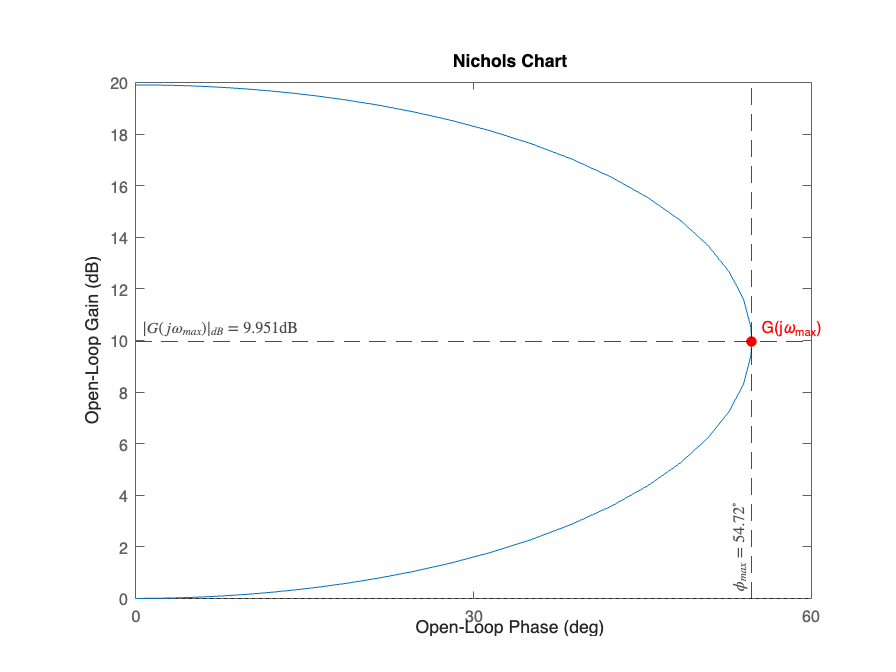

clear 
s = tf('s');

K = 1;
alpha = 0.9;
beta = 8.9;
G = K*(1+s/alpha)/(1+s/beta);

w_max = sqrt(alpha*beta);
[L_max,phi_max] = bode(G,w_max);

figure, hold on
nichols(G)
plot(phi_max,20*log10(L_max),'ro',MarkerFaceColor='r')
text(phi_max,20*log10(L_max)+0.5,' G(j\omega_{max})','Color','red')
xline(phi_max,'--k',['$\phi_{max}= $',num2str(phi_max,4),'$^\circ$'],'labelHorizontalAlignment','left','labelVerticalAlignment','bottom','Interpreter','latex');
yline(20*log10(L_max),'--k',['$|G(j\omega_{max})|_{dB}= $',num2str(20*log10(L_max),4),'dB'],'labelHorizontalAlignment','left','labelVerticalAlignment','top','Interpreter','latex');

Based on this visualisation, a point originally sitting at the origin in the log-polar plane ends up moving to $G(j\omega_{max})$, which is a result of phase lead/advance (moving the point rightwards), and gain increase (moving the point upwards).

#### Example

*Design a controller for the system, *$P(s)=\frac{1}{s^2}$*, which will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, and percentage overshoot of *$25$*%, and achieve zero-error tracking at steady-state for step reference and ramp signals.*

$P(s)$ is Type-2, so we can design $G(s)$ to be Type-0 and still meet the steady-state requirements. Note that there were no requirements regarding disturbance rejection.

Recall that $M_A$, representing the *stay-below *boundary when plotted against a Bode magnitude response, is determined using

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.35$.

For the *stay-above *boundary, we note that $P(s)$ has at least one integrator. For this reason we use the *stay-above *constraint formulation that we first introduced when designing PI controllers. Specifically, we set $M_B=0.98$, and then apply this *stay-above *boundary for all frequencies up until the peak frequency, which is defined as

$\omega_p=\omega_n\sqrt{1-2\zeta^2}=\frac{4}{\zeta T_s}\sqrt{1-2\zeta^2}=1.63$ rad/s.

We then begin by trying to design a P controller of the form $G(s)=K$, by setting $\alpha=\beta$.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)=P(j\omega)G(j\omega)$. Frequency point $\omega=\omega_p$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_0$ to be above the enclosed green region.

clear
s = tf('s');

P = 1/(s^2);
K = 1.5;
alpha = 0.51;
beta = 5.17;

G = K*(1+s/alpha)/(1+s/beta);
L = P*G;

Ts = 5;
OS = 25;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound



figure, hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

nichols(L)
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
xlim([-360,0])

For $K=1$ and $\alpha=\beta$, we see that we are neither satisfying the (green) $|T(j\omega)|\geq M_B$ requirement, nor the (blue) $|T(j\omega)|\leq M_A$ requirement. In fact, our closed-loop system will currently be unstable, as we intersecting the critical point. To rectify this, we first increase $K$ until we closely meet the stay-above boundary. For $K=1.5$ we closely meet the *stay-above *requirement, but our closed-loop system will still be unstable (as well as not meet the overshoot specification). We can now make use of our lead filter to provide the much needed phase lead so that we can avoid entering the blue circle. We choose $\omega_{max}=\omega_p$ as the frequency point at which our lead filter will supply the maximum phase lead (owing to the fact that this point will need to move right, and also end up moving upwards from the gain increase), and then measure that we need at least $45^\circ$, or $\phi_{max}=\frac{\pi}{4}$ radians, of phase lead in order to get out the circle. To be on the safe side, we instead set the maximum phase lead to $55^\circ$ to be sure that we can clear $M_A$ boundary (and avoid failing the overshoot requirement. Using $\omega_{max}=\omega_p=1.63$ rad/s, we can then determine the required zero location of our controller using

$\alpha=\frac{\omega_{max}}{\tan\left(\frac{\phi_{max}+\pi/2}{2}\right)}$,

as determined using the code below.

w_max =1.63;
phi_max = 55*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )
beta = w_max^2/alpha

Checking the time-domain step response shows that we meet both user specifications.

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

Note that we could have selected a maximum phase frequency slightly below $\omega_p$, but because this frequency is where we approximately expect our closed-loop response to have its peak response, this point is likely to end up being closest to the critical point, and by extension, to the overshoot boundary.